# CSX/ECE 6730 Project 1: Orbit Modeling

**Team 57: Blaine Costello, Caitlyn Caggia, Lakshmi Raju**

**March 1, 2019**

## INPUT SETUP

*Additional files: planetData.m*

**Mass Data**

Masses of the Sun and 9 planets (Mercury, Venus, Earth, Moon, Mars, Jupiter, Saturn, Uranus, Neptune, Pluto, respectively) courtesy of [NASA](https://ilrs.cddis.eosdis.nasa.gov/docs/2014/196C.pdf) (page 49). Mass is saved as a 1xN vector as GM in au^3/day^2.

**Position and Velocity Data**

Initial position and velocity vectors were pulled from [NASA data](https://ilrs.cddis.eosdis.nasa.gov/docs/2014/196C.pdf) for June 28, 1969 (page 47).

The barycenter of the Solar System is used as the observation point of reference.  Distances are in au and velocities are in au/day. Positions and velocities are saved in 3xN vectors.

**Expected Values**

Actual positions and velocities for June 28, 1970 were pulled from NASA JPL data through Matlab's built-in `planetEphemeris()` function. These values have less significant figures than the data for 1969 above, but are useful to compare each model's calculations to the real position of each body.

Note that Matlab's Aerospace Toolbox (available with the Georgia Tech's Matlab licenses for free) as well as the Ephemeris Data add-on (available through [Mathworks](https://www.mathworks.com/matlabcentral/fileexchange/46671-ephemeris-data-for-aerospace-toolbox) for free) are needed to use this function. These packages use data from NASA's Jet Propulsion Laboratory (JPL) ephemeris [database](https://ssd.jpl.nasa.gov/?planet_eph_export). 

clear all; close all;
addpath('Data');
run planetData.m;

## COWELL'S METHOD

*Additional files: cowells.m, cowellsExample.avi*

**Background**

Cowell's method for orbital simulation simply sums the Newtonian forces on a body of *i *from the other bodies *j:*


$$\ddot{\mathbf{r}}_i = \sum_{j=1,{j \neq i}}^{n}   \frac{Gm_{j}( \mathbf{r}_j - \mathbf{r}_i)}{r_{ij}^3}$$


where

    $\ddot{\mathbf{r}}_i$ is the acceleration vector of body *i*

*    G *is the gravitational constant ($6.674 \times 10^{-11} \:\mathrm{m}^{3} \,\mathrm{kg}^{-1} \,\mathrm{s}^{-2}$)

    $m_j
$ is the mass of body j

    $\mathbf{r}_i$ and $\mathbf{r}_j$ are the position vectors of objects *i * and *j*

    $r_{ij}$ is the distance from object *i* to object *j*

with all vectors relative to the barycenter of the system.

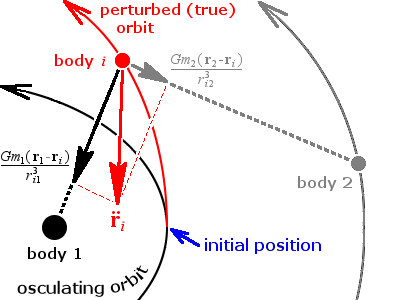

*Forces from preturbing bodies (black and gray) are summed to form the total force on the body of interest (red). Thus the true (red) orbit deviates from the original unpreturbed orbit (black). Image courtesy of *[*Wikimedia*](https://upload.wikimedia.org/wikipedia/commons/3/30/Cowells_method.png)*. *

While this method is the among the simplest to use, it has high error when handling large perturbations (for example, when two objects nearly miss each other) and requires a large degree of arithmetic precision when the mass of the bodies varies greatly.

**Cowell's Method Example**

The situation to be simulated is the orbital movement of a system of 10 bodies around the Sun: Mercury, Venus, Earth, Moon, Mars, Jupiter, Saturn, Uranus, Neptune, Pluto. To do this, Cowell's Method is used to estimate the perturbations of the bodies on each other and model the movement of the system. 

Run the simulation for one full year (on Earth).

[finalPos, finalVel] = cowells('cowellsExample.avi', 365, 100, true);
%implay('cowellsExample.avi')

The simulation was also run to simulate just the Moon around the Earth. The Cowell's Method code allows for N bodies, simply changing the constants in the planets.mat file which is loaded in line 10 in the cowells.m function to include the wanted bodies, allows for various simulations. 

load planets.mat masses positions velocities N;
masses11 = masses; positions11 = positions; velocities11 = velocities; N11 = N; %Saving old data
masses = masses(4:5); positions = positions(:,4:5); velocities = velocities(:,4:5); N = 2;
save('planets', 'masses', 'positions', 'velocities', 'N');
[finalPos2, finalVel2] = cowells('cowellsExample2.avi', 365, 100, true);
implay('cowellsExample2.avi')
save('planets', 'masses11', 'positions11', 'velocities11', 'N11'); %Reverting planets.mat back to 11 body system

**Cowell's Method Error**

The calculated values were compared against actual measurements with a simple percent error calculation for position and velocity.

load planetsExpected.mat expectedPos expectedVel names;
errorPos = (finalPos-expectedPos)./expectedPos .* 100;
errorVel = (finalVel-expectedVel)./expectedVel .* 100;
cowellError = [num2cell(errorPos); num2cell(errorVel)];
rownames = [{'% error in x-position'}; {'% error in y-position'}; ...
    {'% error in z-position'}; {'% error in x-velocity'}; ...
    {'% error in y-velocity'}; {'% error in z-velocity'}];
cowellTable = cell2table(cowellError);
cowellTable.Properties.RowNames = rownames;
cowellTable.Properties.VariableNames = names;
display(cowellTable)

cowellTable = 6×11 table
                               Sun      Mercury     Venus      Earth        Moon         Mars       Jupiter       Saturn        Uranus       Neptune         Pluto   
                             _______    _______    _______    _______    ___________    _______    __________    _________    __________    __________    ___________

    % error in x-position     -4.919    -706.21    -193.35    -751.09     4.3814e+06    -21.174      0.037883     0.007254    0.00089024     0.0001636     0.00016089
    % error in y-position    -4.3812     -375.2    -523.04    -5.198

% Excluding the Moon...
noMoonPos = [errorPos(:,1:4) errorPos(:,6:end)];
noMoonVel = [errorVel(:,1:4) errorVel(:,6:end)];
avgPosError = sum(sum(noMoonPos)) / (length(noMoonPos));
avgVelError = sum(sum(noMoonVel)) / (length(noMoonVel));
sprintf(['Average Position Error: %4.1f%%\n'...
    'Average Velocity Error: %4.1f%%'], avgPosError, avgVelError)

ans =     'Average Position Error: -396.2%
     Average Velocity Error: -253.9%'


Some analysis/explanation of error and why it is absurdly high for the moon (we don't have the moon in a nice orbit around earth?)

## ENCKE'S METHOD

*Additional files: enckes.m, enckesExample.avi*

**Encke's Method Background**

details

**Encke's Method Example**

% [finalPos, finalVel] = enckes('enckesExample.avi', 365, 10);
% implay('enckesExample.avi')

**Encke's Method Error**